# Occlusion

#### Fred liu 2022.5.20

**載入模型與影像(Load Model & Image)**

net = trainedNetwork_1;
img = imread("86_AL.jpg");

**影像辨識(Image Classify)**

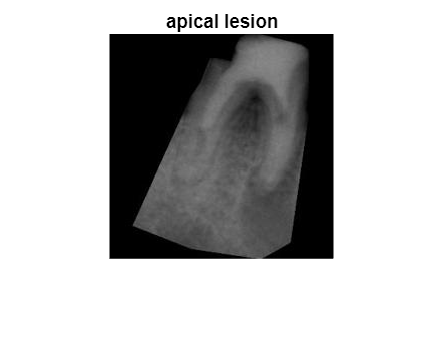

inputSize = net.Layers(1).InputSize(1:2);
re_img = imresize(img,inputSize);
figure,imshow(re_img)

[label,scores] = classify(net,re_img);
title(char(label))

**影像可視化(Image Occlusion)**

scoreMap = occlusionSensitivity(net,re_img,label);

**顯示熱圖(Show ScoreMap)**

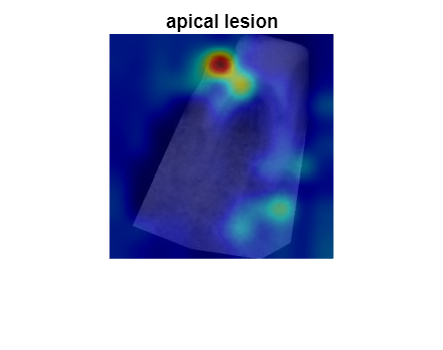

figure
imshow(re_img),hold on
imagesc(scoreMap,'AlphaData',0.5);
colormap jet
title(char(label))

**前兩高類別(Top 2  Class)**

%% List top 2 class scores
[ssort, sidx] = sort(scores, 'descend');

numTopClasses = 2; % show top N choices
TopClasses = net.Layers(end).ClassNames(sidx(1:numTopClasses));
TopScores = ssort(1:numTopClasses)';

topTable = table(TopClasses, TopScores)

topTable = 2×2 table
       TopClasses        TopScores
    _________________    _________

    {'apical lesion'}     0.98677 
    {'normal'       }     0.01323 


**第二高類別顯示(Second Class Show)**

% %% 
% scoreMap = occlusionSensitivity(net,re_img,TopClasses{2});
% %%
% figure,imshow(re_img)
% hold on
% imagesc(scoreMap,'AlphaData',0.5);
% colormap jet
% title(char(TopClasses{2}))